# `MATISSE`: 2) The Lexis Diagram

## Overview

- The Lexis diagram is a fundamental construct in epidemiology, demography, and sociology

- Lexis diagrams are represented in `MATISSE` using the `rates` class

close all
clear
clc

## Example: Select 1

Example = 16;

DELTA = 1;

 

r = ratesdata(Example);

switching to data directory . . .
                   . . . and back


switch DELTA
    case 1
        R0 = r;
    case 2
        R0 = chunk(r, 'AgeBlock', 2, 'PerBlock', 2);
    case 5
        R0 = chunk(r, 'AgeBlock', 5, 'PerBlock', 5);
end


*Add a small value to any zero cells using the *`rates/fill`* method  . . .*

R = fill(R0);

## Basic statistics: the `disp` and `uni` methods 

MATLAB always dispatches a `disp` method whenever you type the name of an object from the command line. The `disp` method for `rates` objects provides a brief snaphot.

disp(R)

melanoma  F  NHW
 
  *   50 age groups 35 through 84.
  *   29 calendar periods 1992 through 2020.
  *   78 nominal birth cohorts 1908 through 1985.
 
  #   events:  min 10.0   mean 43.7   max 106.0   
 
63331 total events in 156798589 PY.


You can also type the name of an object at the command line without ending that line with a semicolon:

R

R = melanoma  F  NHW
 
  *   50 age groups 35 through 84.
  *   29 calendar periods 1992 through 2020.
  *   78 nominal birth cohorts 1908 through 1985.
 
  #   events:  min 10.0   mean 43.7   max 106.0   
 
63331 total events in 156798589 PY.

The `uni` method produces additional statistics for any collection of one or more rates objects, regardless of size. For example, the values of  `R` and `R0` will be slightly different **if **any zeros needed to be filled.

uni(R, R0)

ans = Univariate Statistics
           melanoma  F  NHW melanoma  F  NHW
A                        50               50
P                        29               29
C                        78               78
nmiss                     0                0
nmiss pct                 0                0
nz                        0                0
nz pct                    0                0
min E                    10               10
mean E               43.677           43.677
max E                   106              106
Total E               63331            63331
Total O           1.568e+08        1.568e+08
ASR(1)               26.087           26.087
ASR(P)                43.31            43.31
seer                 2.2615           2.2615
seer Lo              1.9773           1.9773
seer Hi              2.5464           2.5464
 

If the raw data has lots of zeros your statistical analyses may be unstable. In that situation, you will probably be better off 'chunking' the rates up to a larger bin size, as specified by the vaue of  `DELTA `used in the `rates/chunk `method illustrated in the preceding section. You can identify an appropriate value of  `DELTA `by trial and error.

## Visualization: the `pcolor and` `surf `methods

- The `rates/pcolor` method always display the **absolute rates**

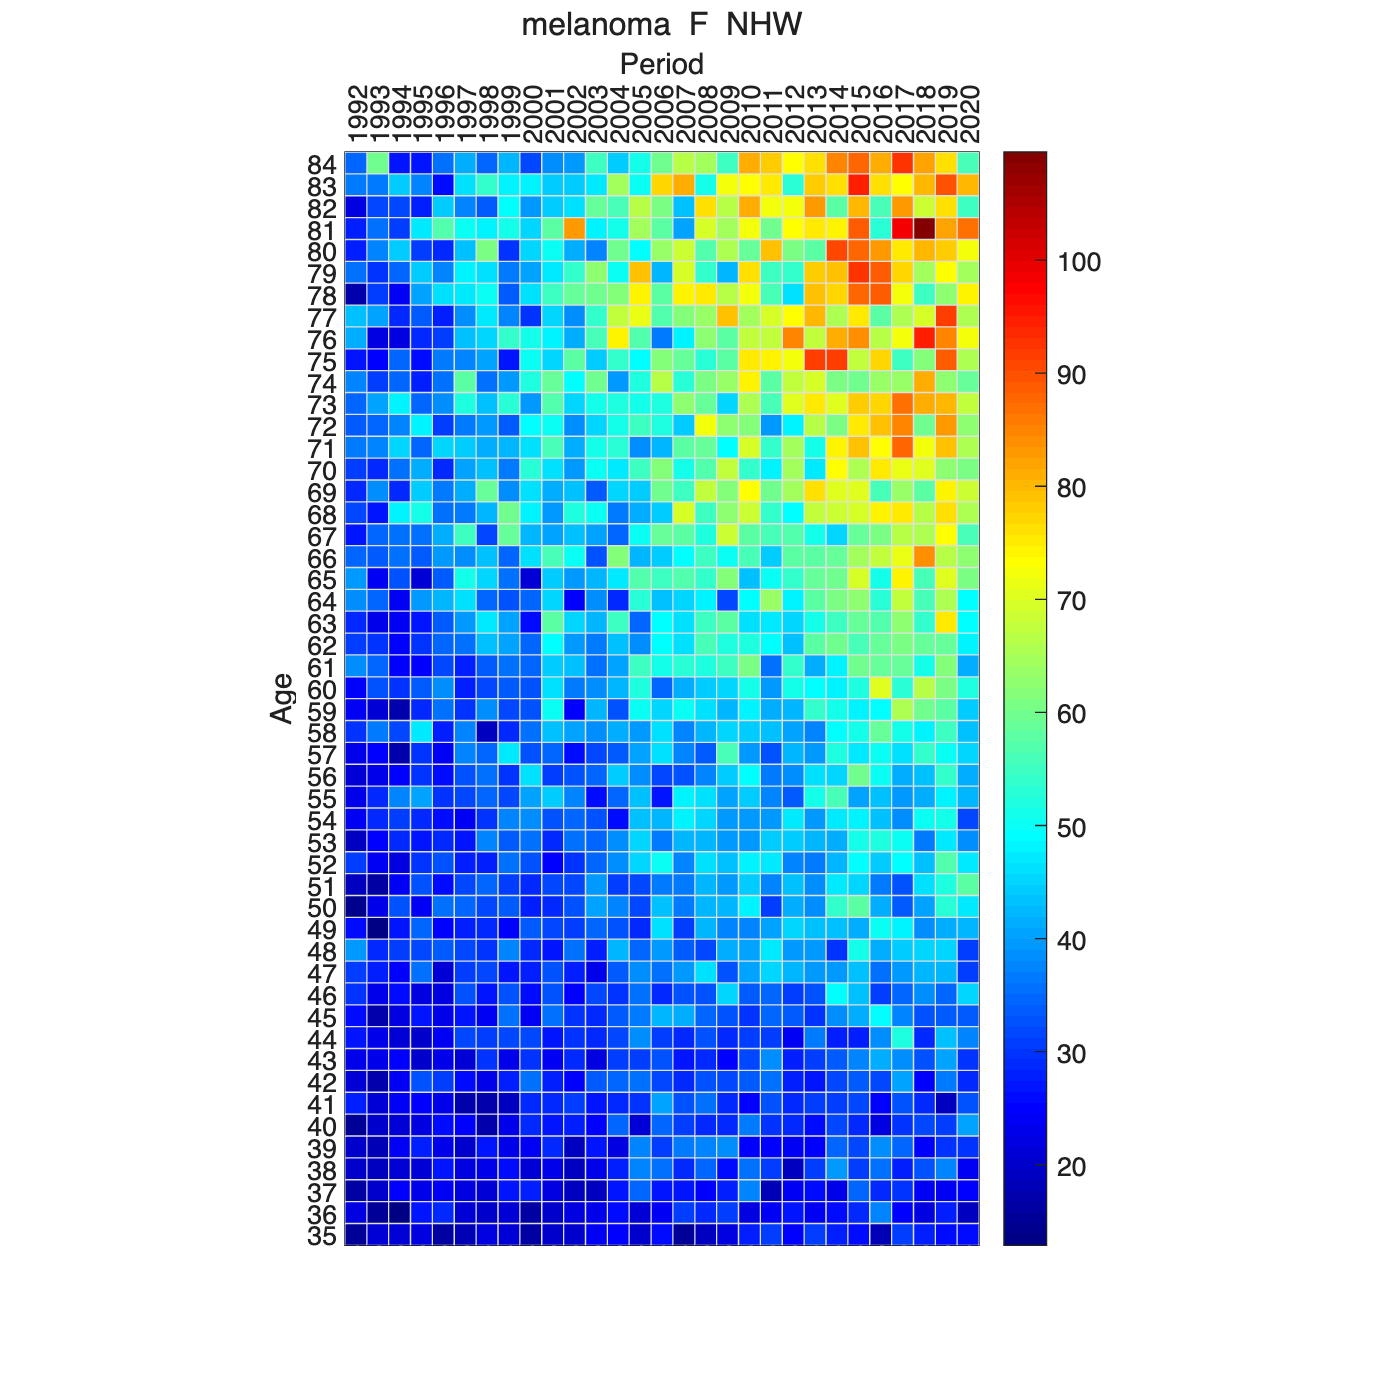

figure('Position', [0 0 700 700])
pcolor(R)

- The `rates/surf` method always displays the **log** rates

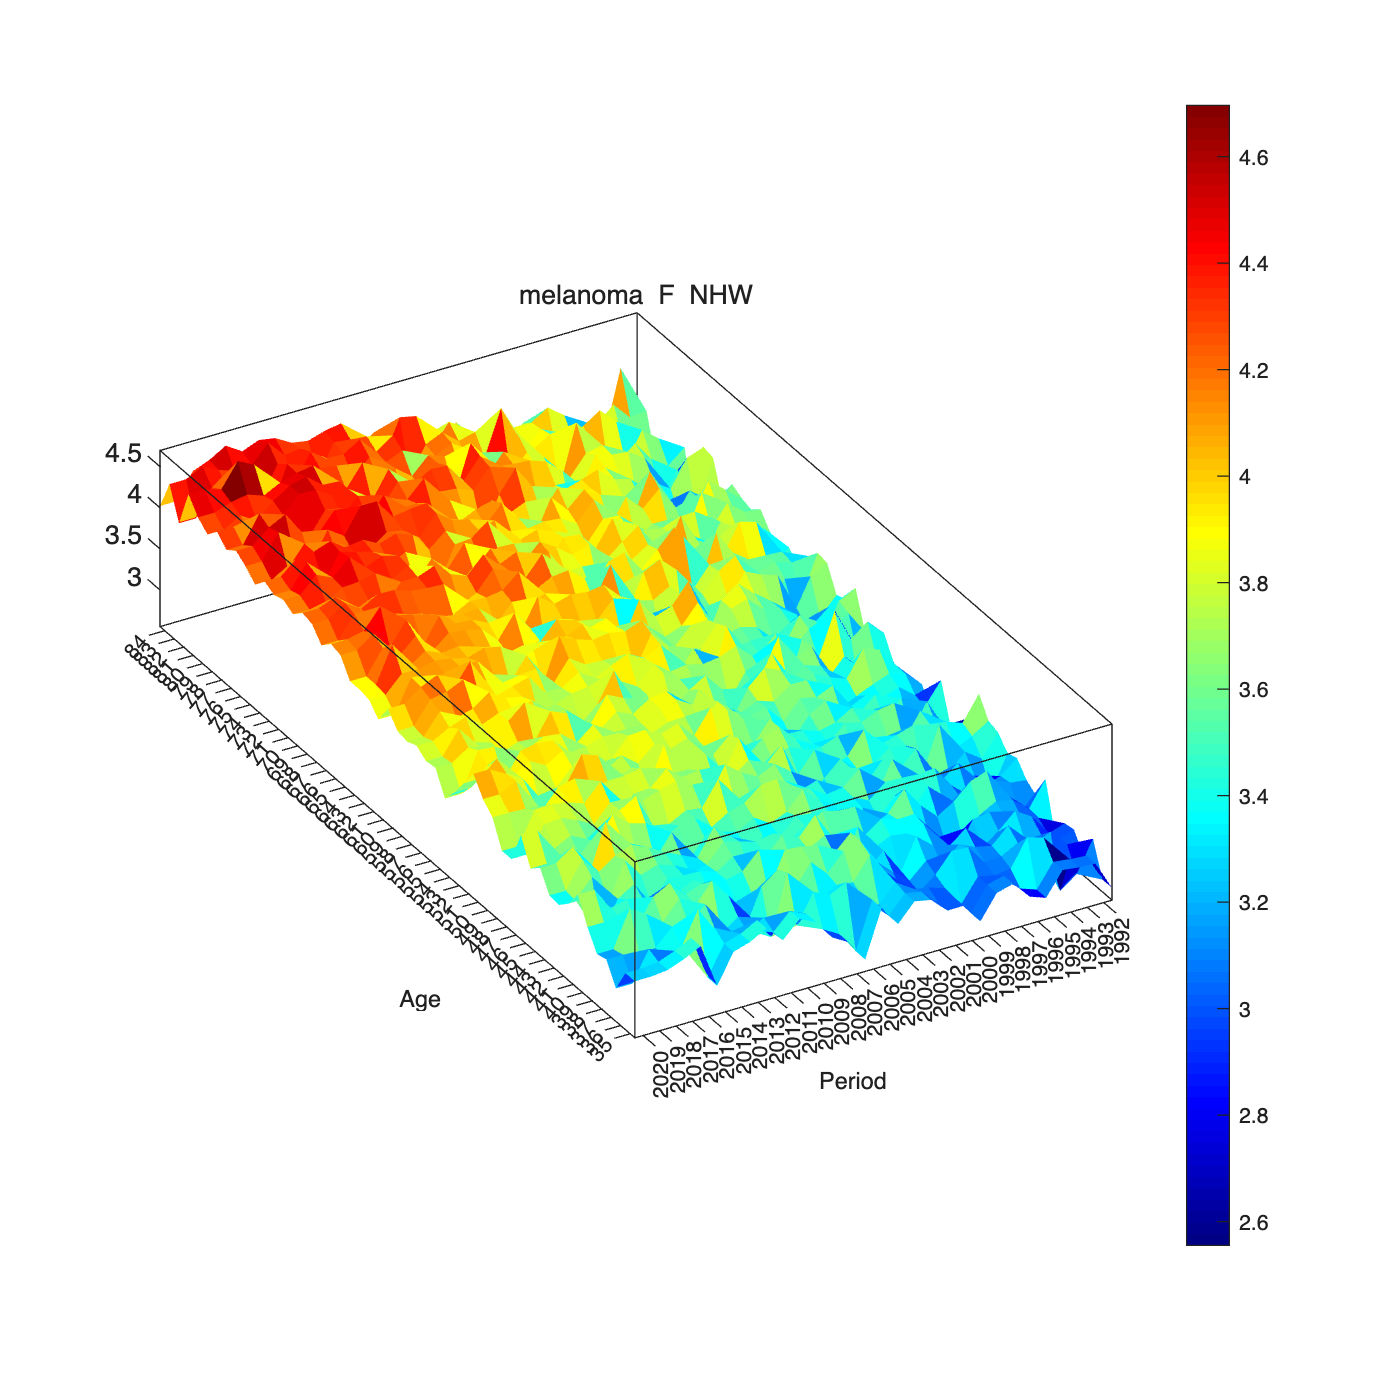

figure('Position', [0 0 700 700])
surf(R)

### Variations

There are two ways to tune the appearance of a plot:

- post hoc from the command line using universal MATLAB commands (e.g., the left [`subplot`](https://www.mathworks.com/help/releases/R2025b/matlab/ref/subplot.html?searchHighlight=subplot&s_tid=doc_srchtitle) below) . . .

figure('Position', [0 0 1200 600])
subplot(1, 2, 1) 
surf(R)
colormap nepal
colorbar off
shading faceted
set(gca, 'FontSize', 6)

- or up front using MATISSE's `go` values and/or the `ego` function (right `subplot`)

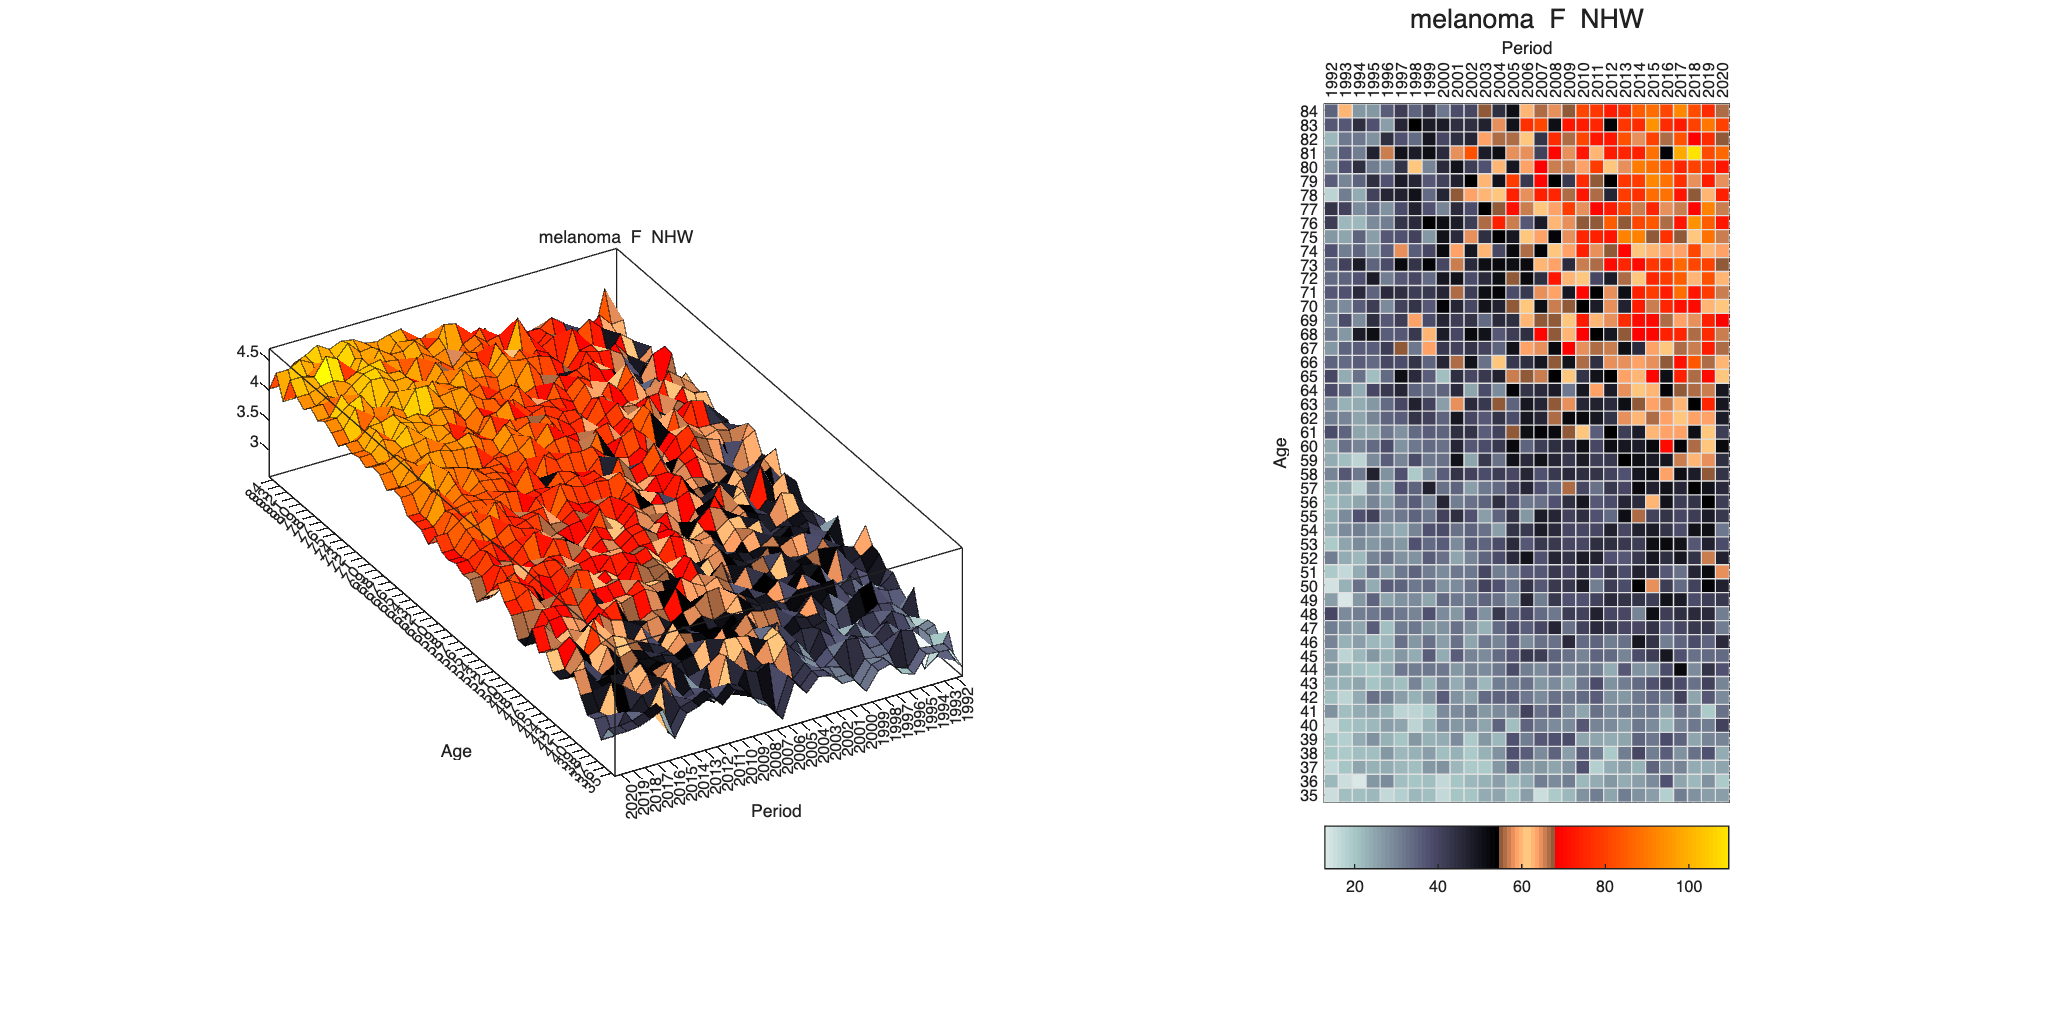

subplot(1, 2, 2)
pvp1 = ego('class', 'rates', 'method', 'pcolor');
pvp1.colormap = 'nepal';
pvp1.FontSize = [6 6 10];
pvp1.colorbar = 'southoutside';

subplot(1, 2, 2)
pcolor(R, pvp1)

### The `lexis` method

The `lexis` method illustrates the relationships between Lexis diagrams and standard plots (**described in Section 3**)

Recall our fundamental notation: 

 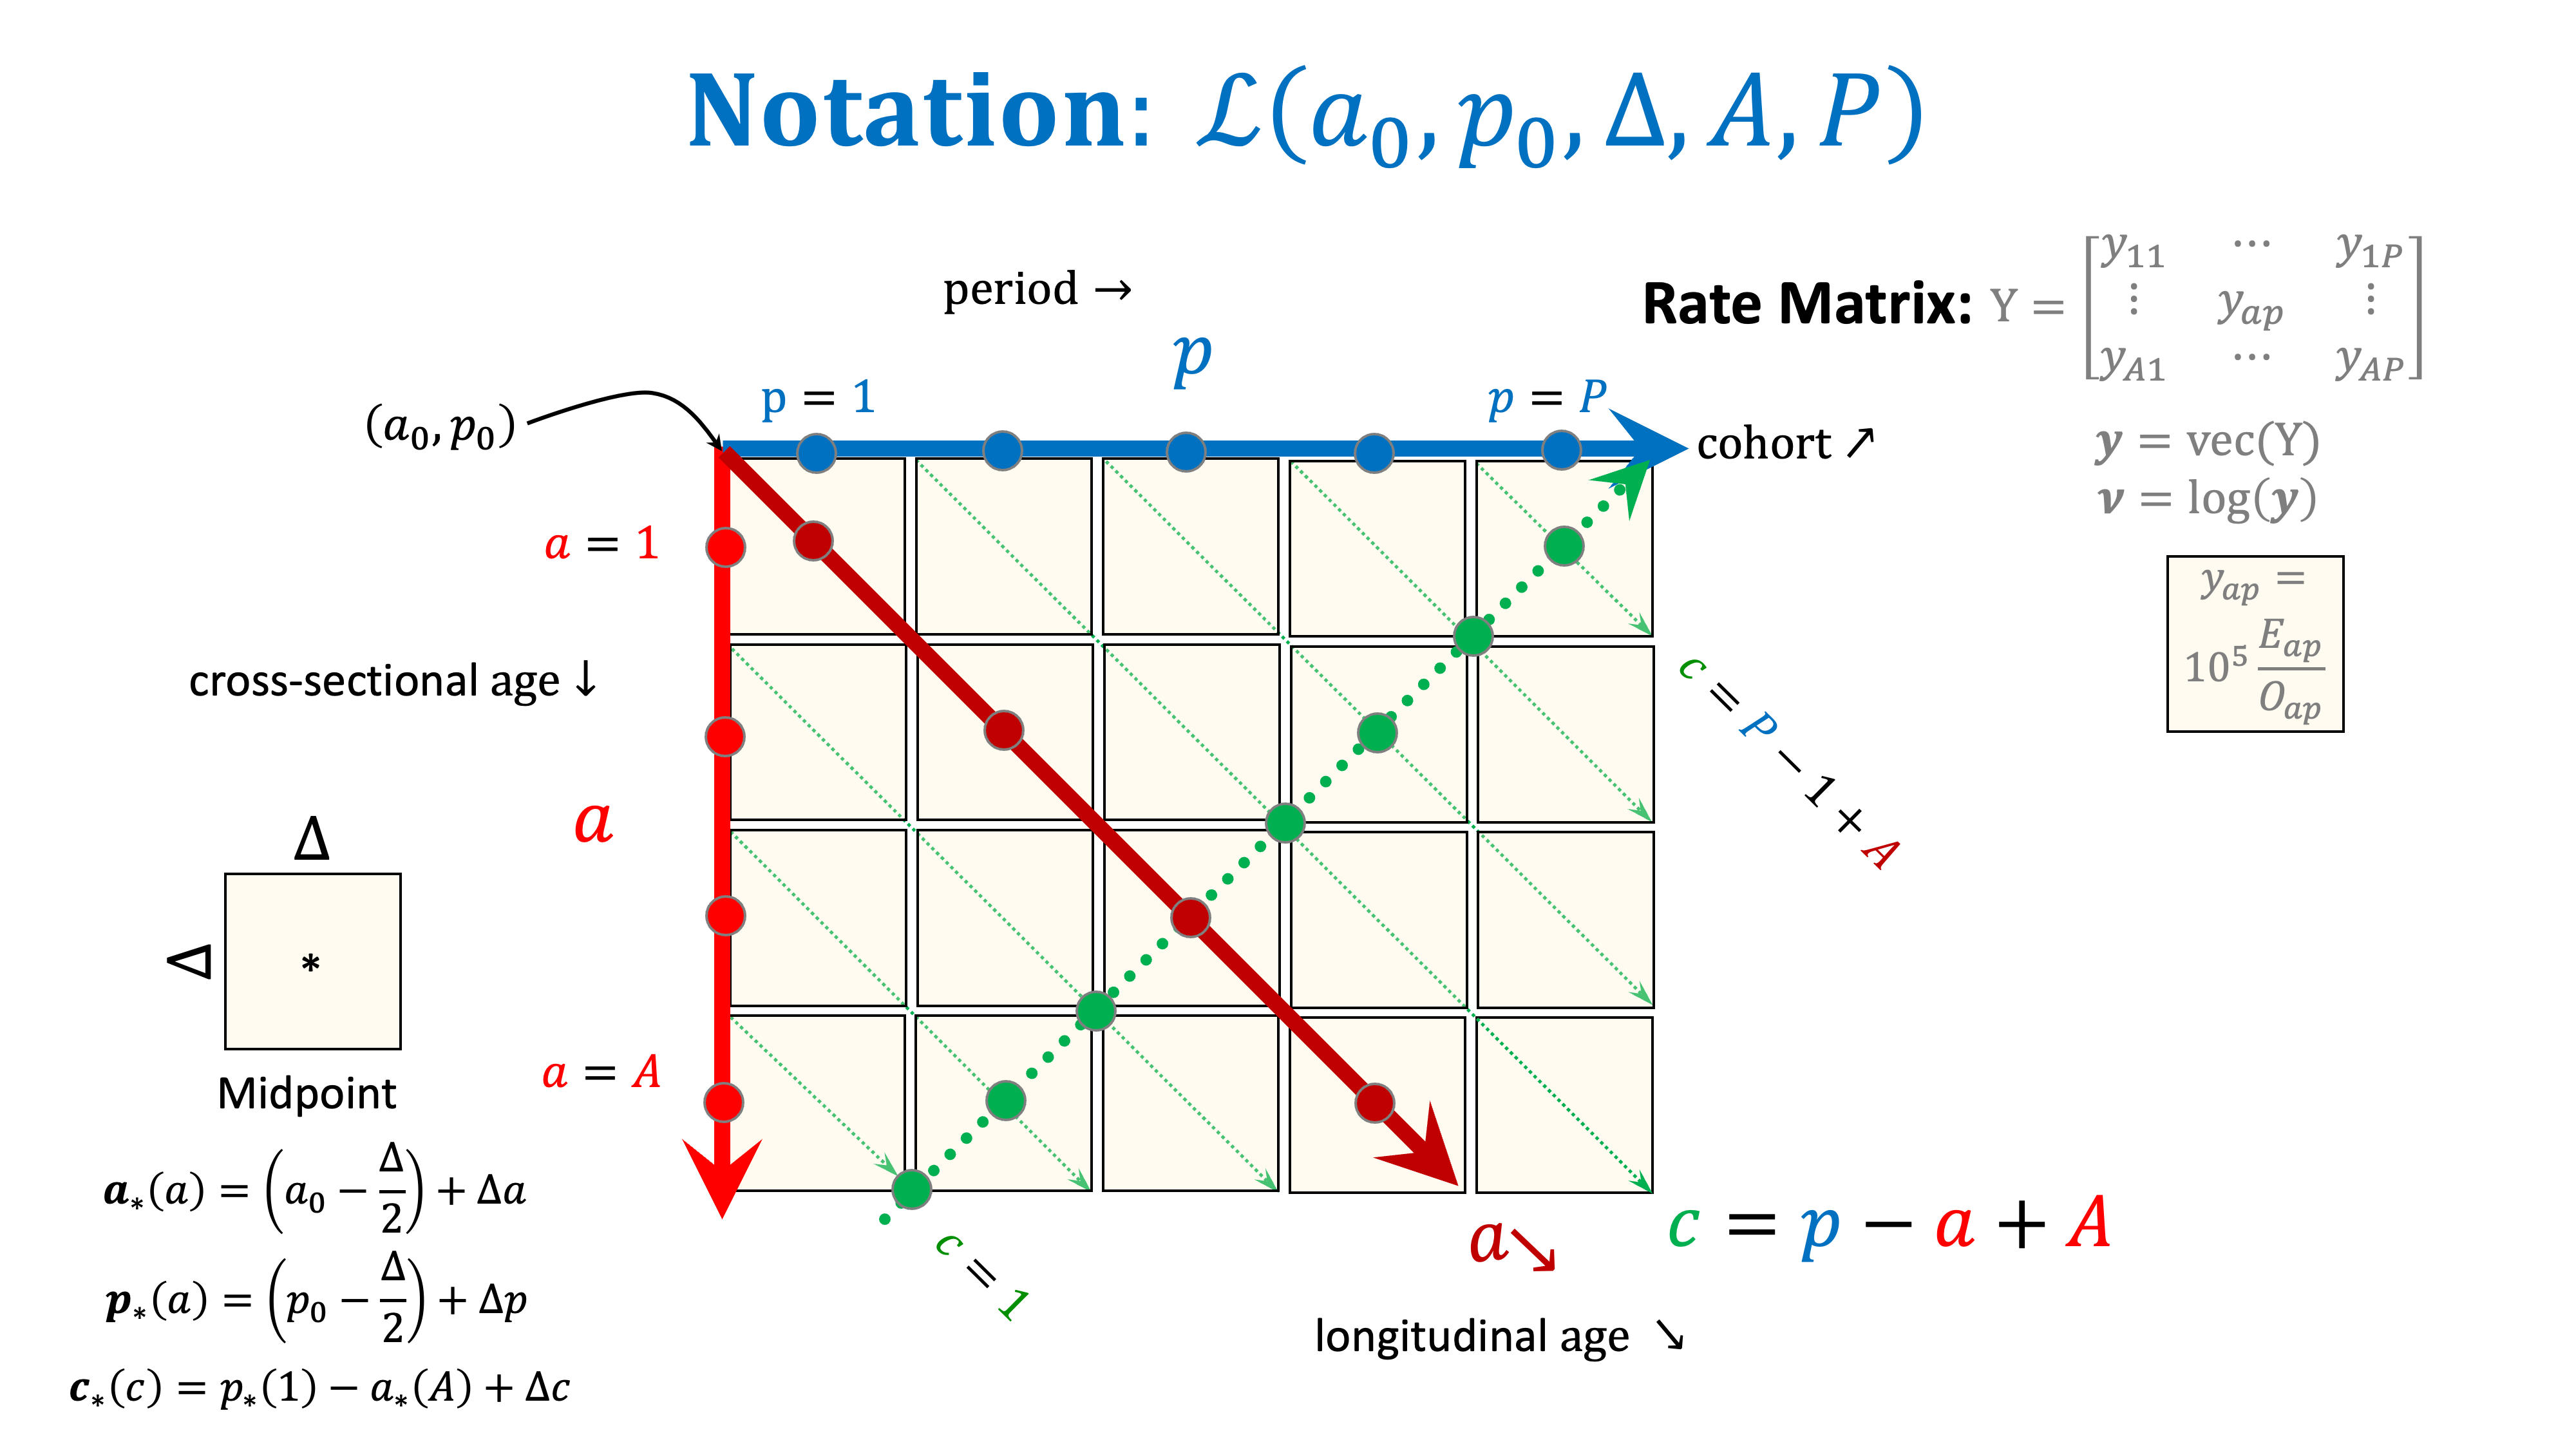

We can rotate the axes from cross-sectional age and cross-sectional period to longitudinal age and cross-sectional cohort - for clarity, we need to insure that the aspect ratio in the rotated plot remains the same. This is done for us by the `rates/lexis `method.

The `rates/lexis` method makes an important **theoretical** point

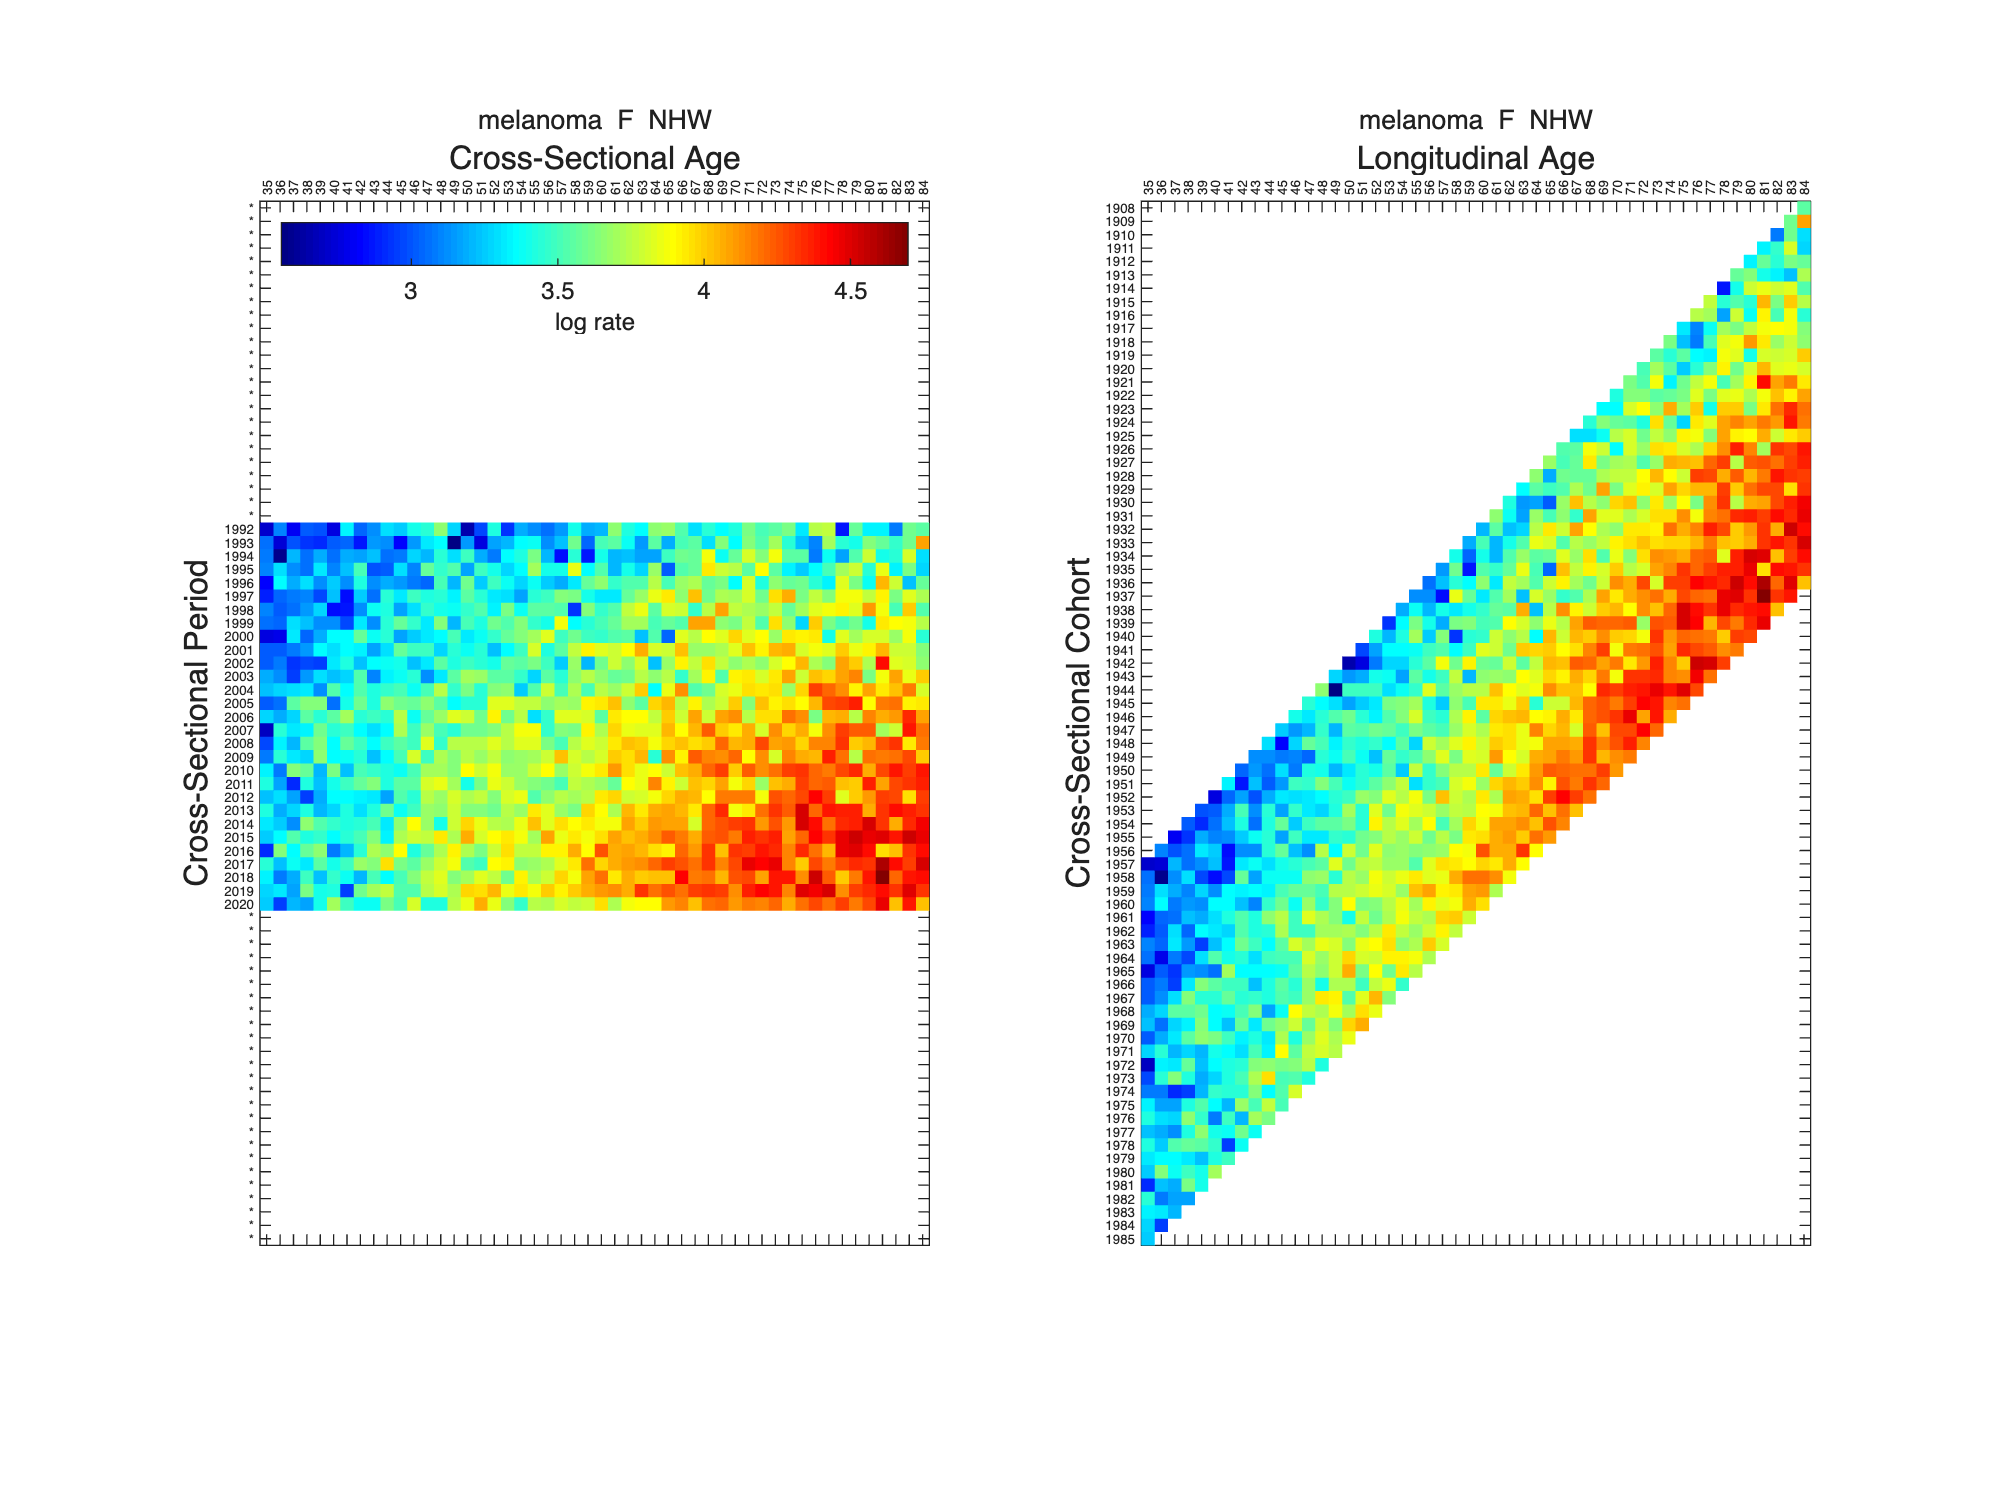

lexis(R, 'pcolor')

When we slice the first plot along it's columns and rows we obtain two of the standard plots described in Section 3

- $r_{p|a} \;$and $r_{a|p}$ respectively

 When we slice the second plot along **it's** columns and rows we obtain the other two standard plots

- $r_{c|a}$ and $r_{a|c}$ respectively

There are many ways to tune the appearance

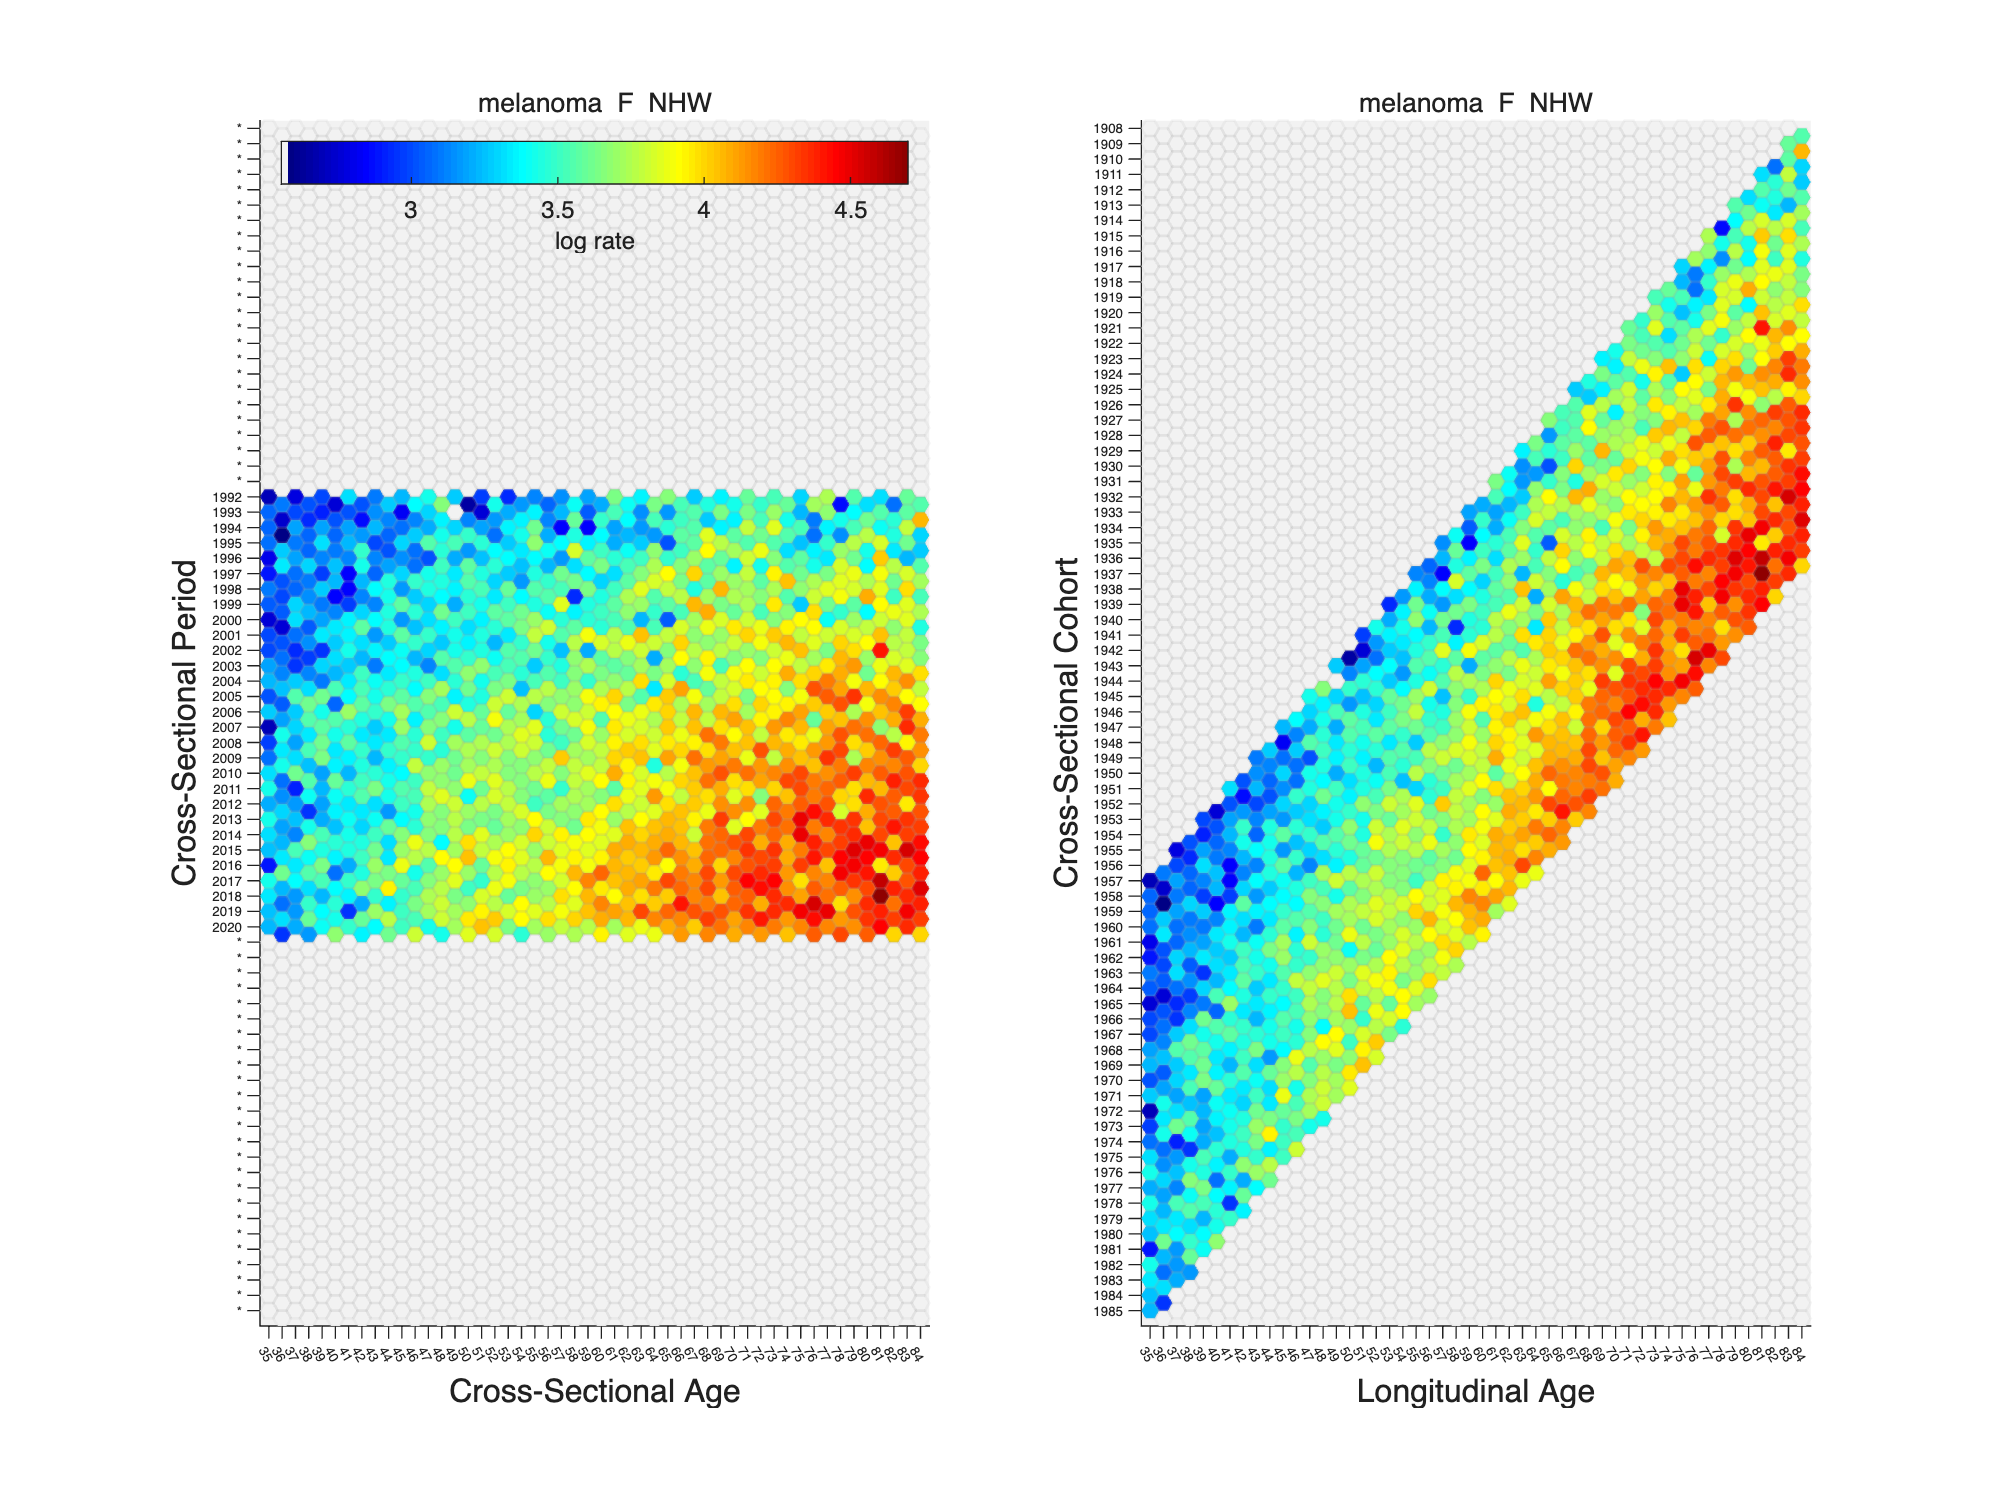

pvp = ego('class', 'rates', 'method', 'lexis');
pvp.EdgeAlpha = 0.10;
lexis(R, 'hexmap', pvp) % choose 'pcolor' or 'hexmap' - a stylish alternative

## Multiple Lexis diagrams

We seldom analyze a single Lexis diagram in isolation

In this section we extract log rates from 4 `rates` objects using the `rates/type` method, and then use two of MATISSE's specialized graphics functions to view the ensemble.

We will be putting the data in a [cell array](https://www.mathworks.com/help/releases/R2025b/matlab/ref/cell.html?searchHighlight=cell&s_tid=doc_srchtitle).  MATISSE makes extensive use of this important MATLAB class.

### Examples: Select 4

num1 = 1;
num2 = 3;
num3 = 2;
num4 = 4;

**Block Size**

DELTA = 2;

r4 = ratesdata([num1 num2 num3 num4]);

switching to data directory . . .
                   . . . and back


t4 = cell(1, 4);
for i = 1:4

    %%%
    % For examples 11 - 16 we will remove calendar years 2019 and 2020 so
    % that these examples can be combined with examples 1 - 10
    %%%

    if eq(size(r4{i}, 2), 29)
        r4{i} = r4{i}(:, 1:27);
    end

    r4{i} = chunk(r4{i}, 'AgeBlock', DELTA, 'PerBlock', DELTA);
    t4{i} = type(r4{i}, 'comp', 'lr');

end

disp(uni(r4{:}))

Univariate Statistics
           F ER+ breast NHB F ER- breast NHB F ER+ breast NHW F ER- breast NHW
A                        25               25               25               25
P                        13               13               13               13
C                        37               37               37               37
nmiss                     0                0                0                0
nmiss pct                 0                0                0                0
nz                        0                0                0                0
nz pct                    0                0                0                0
min E                    23           5.0714           176.72           60.834
mean E               133.79           43.312           1174.7           202.74
max E                 300.6            97.52           2400.6           399.09
Total E               43481            14076       3.8178e+05            65891
Total O      

### Visualization: the` thumbnail` and `vistagram` methods

The `thumbnail` and `vistagram` methods generalize the `pcolor` and `surf `methods when we are examining 2 or more `double`, `tbl`, `matrix` or `rates` objects all the same size. 

`thumbnail`

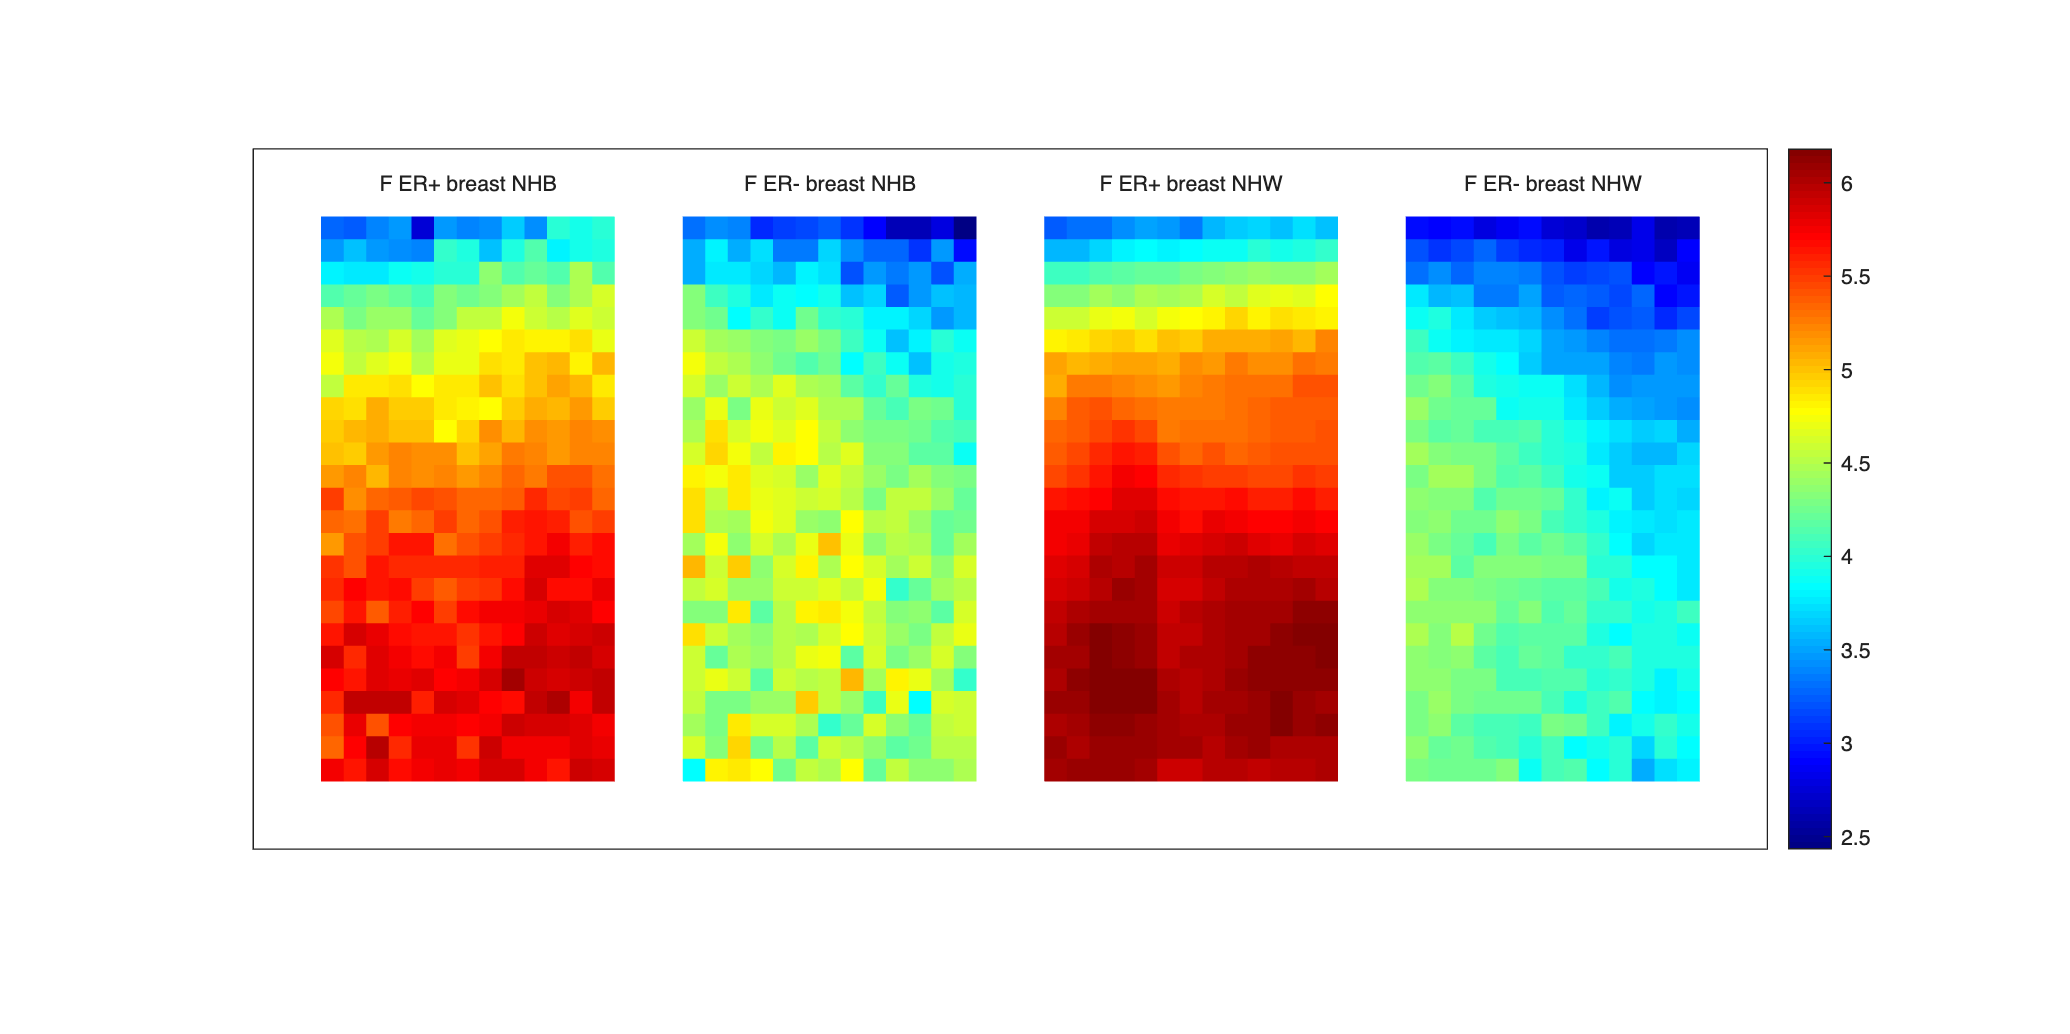

figure('Position', [0 0 1200 600])
thumbnail(t4)

`vistagram`

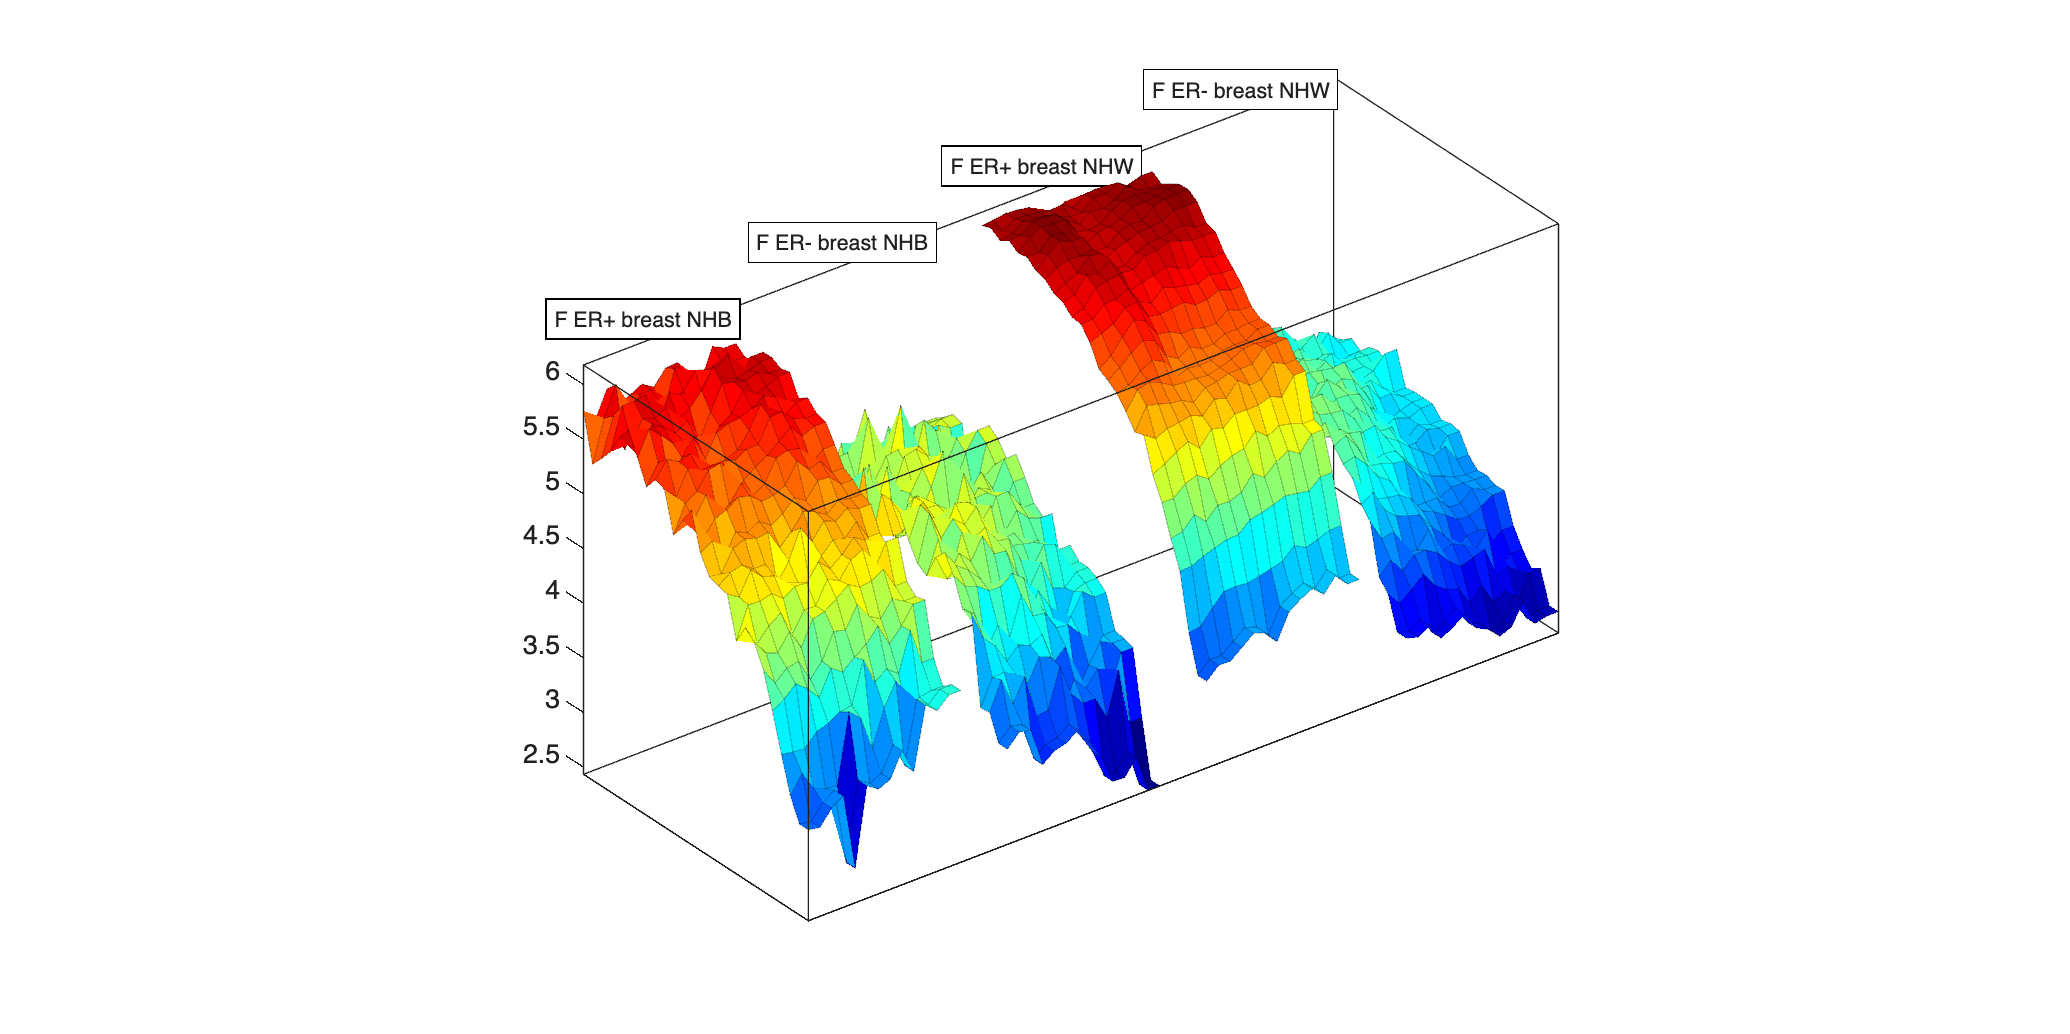

figure('Position', [0 0 1200 600])
pvp2 = ego('class', 'graphics', 'method', 'vistagram');
pvp2.colorbar = '';

vistagram(t4, pvp2)